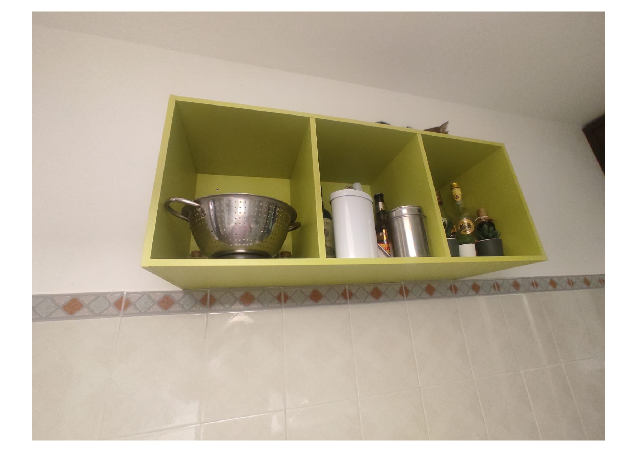

% Step 1: Manually select 6 points for the conic
figure;
imshow(img); % Display the image

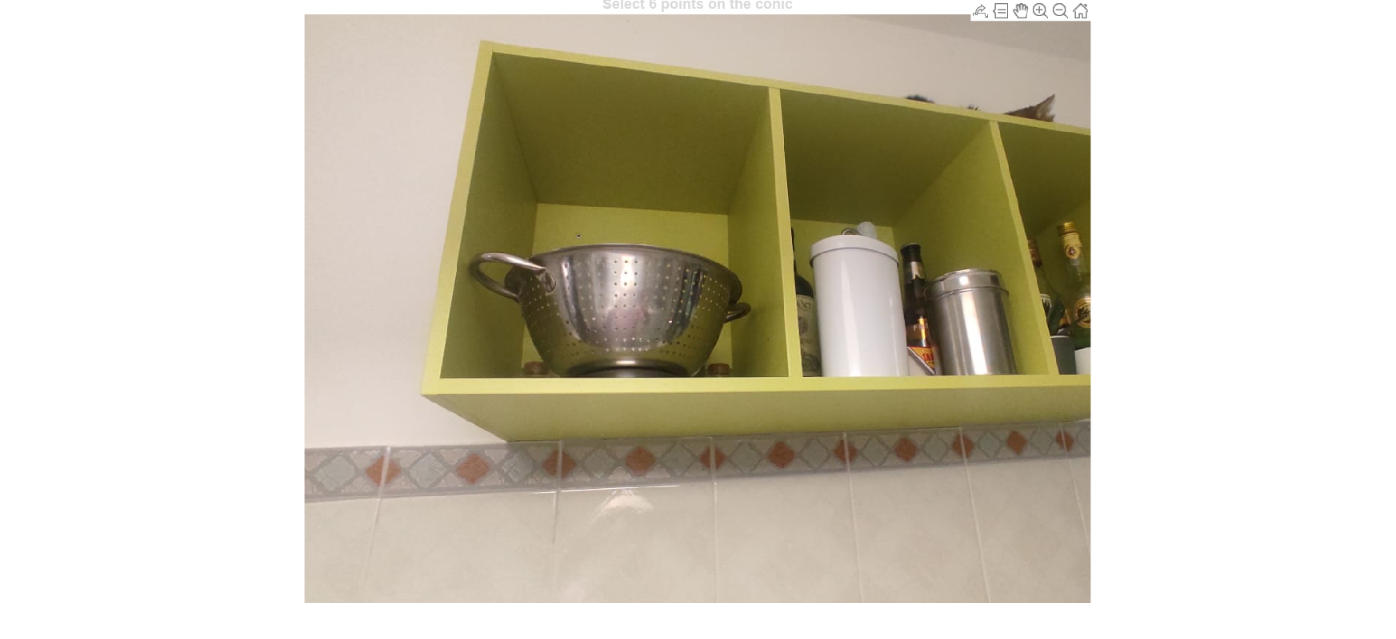

title('Select 6 points on the conic');
hold on;
[conic_x, conic_y] = getpts; % Select 6 points
hold off;

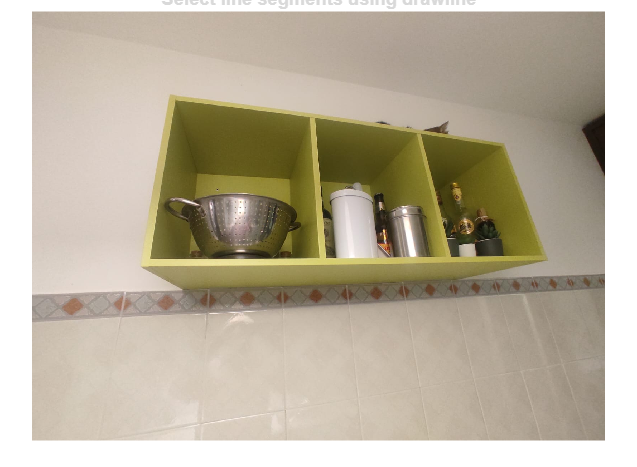


% Step 2: Create the data matrix A1 for the conic
% Equation: ax^2 + bxy + cy^2 + dx + ey + f = 0
n_points = length(conic_x);
A1 = [conic_x.^2, conic_x.*conic_y, conic_y.^2, conic_x, conic_y, ones(n_points, 1)];

% Step 3: Solve for the conic coefficients using SVD
[~, ~, V1] = svd(A1); % Perform SVD on A1
conic_coeffs = V1(:, end); % Extract the last column of V1
conic_coeffs = conic_coeffs / conic_coeffs(1); % Normalize to ensure a = 1
[a, b, c, d, e, f] = deal(conic_coeffs(1), conic_coeffs(2), conic_coeffs(3), ...
                          conic_coeffs(4), conic_coeffs(5), conic_coeffs(6));

% Step 4: Manually select segments and convert to lines in homogeneous coordinates
figure;
imshow(img); % Display the image
title('Select line segments using drawline');
hold on;

h_lines = {}; % Store homogeneous line representations
for i = 1:desired_number_of_lines
    segment = drawline; % Manually draw a line segment
    pos = segment.Position; % Get the endpoints of the line segment
    h_line = segToLine(pos); % Convert segment to homogeneous line
    h_lines{end+1} = h_line; % Store the line
end

Unrecognized function or variable 'desired_number_of_lines'.

hold off;

% Step 5: Manually select 12 points for the curve S
figure;
imshow(img); % Display the image
title('Select 12 points for the curve S');
hold on;
[curve_x, curve_y] = getpts; % Select 12 points
hold off;

% Step 6: Save all data into .mat files
% Save lines and conic
hz = []; % Placeholder for horizon line (if applicable)
lines_and_conics = struct('lines', h_lines, 'hz', hz, 'conic', conic_coeffs);
save('lines_and_conics.mat', 'lines_and_conics');

% Save the curve S
S = [curve_x'; curve_y']; % Store the points of the curve as a 2x12 matrix
save('ss.mat', 'S');

disp('Data saved successfully into lines_and_conics.mat and ss.mat.');
